% %Se crea una señal sinusoidal 
% t = 0:1:300;
% fs = 100;
% t = t / fs;
% f = 5;
% y = sin(2*pi*f*t);
% yc= square(2*pi*f*t);
% %Se grafica la función
% plot(t,y);
% plot(t,yc);
% 
% %Se hace la transformada de Fourier a la función y
% tf = fft(y,1024);
% tfc = fft(yc,1024);
% 
% %Se calcula la magnitud de la nueva función
% m = abs(tf)
% mc = abs(tfc)
% f= (-fs/2:fs/1024:fs/2);
% f(end) = [];
% plot(f,m)
% plot(f,mc)

Pruebas

ft = 5

fst = 100

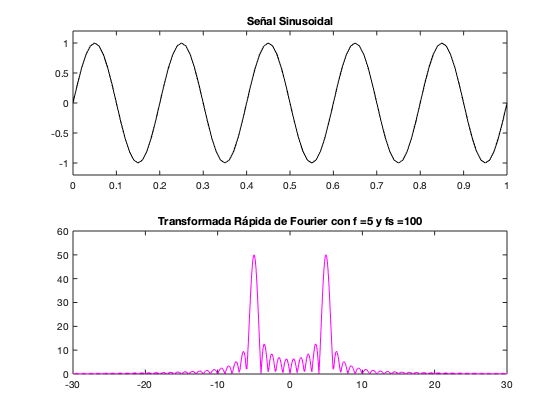

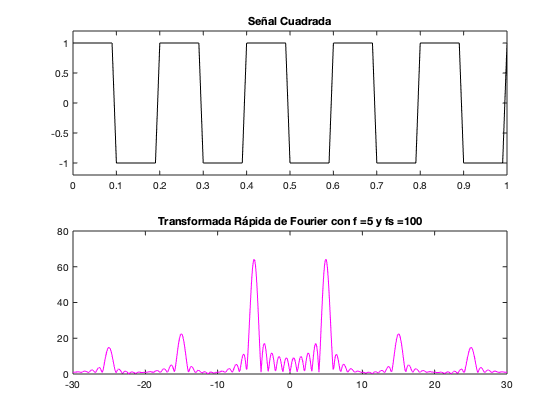

%Primera Prueba 
f = 5;
fs = 100;

PDS_P3(f,fs)

ft = 10

fst = 100

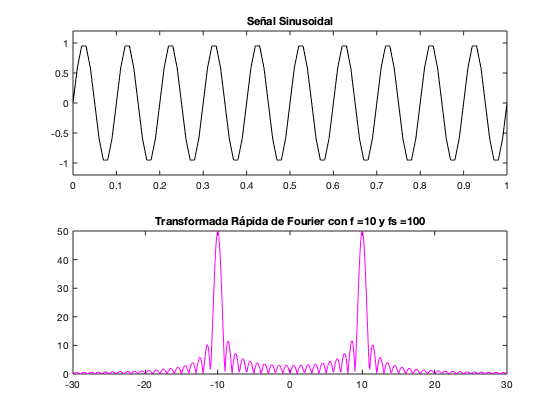

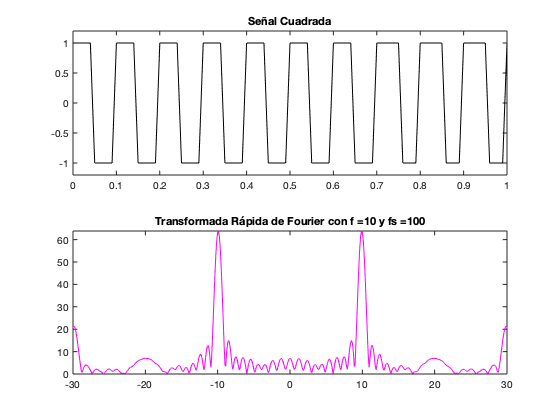


%Segunda Prueba 
f = 10;
fs = 100;

PDS_P3(f,fs)

ft = 5

fst = 50

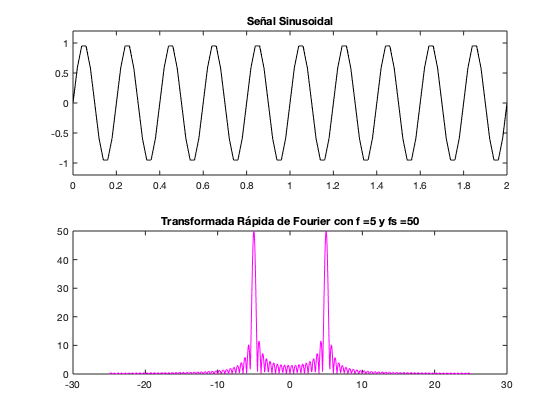

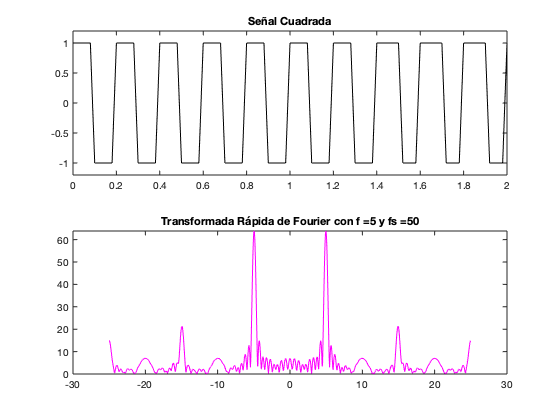


%Tercera Prueba 
f = 5;
fs = 50;

PDS_P3(f,fs)

ft = 10

fst = 100


%Cuarta Prueba
f = 10;
fs = 100;

PDS_P3(f,fs)

Función

function [] = PDS_P3 (f,fs)
ft = f
fst = fs
t=(0:1:100)/fs;
y = sin(2*pi*f*t);
x = square(2*pi*f*t);

tfy = fft(y,1024);
tfy = fftshift(tfy);
tfx = fft(x,1024);
tfx = fftshift(tfx);

my = abs(tfy);
mx = abs(tfx);

f = (-fs/2:fs/1024:fs/2);
f(end)= [];

figure
    subplot(2,1,1)
    plot(t,y, 'k')
    ylim([-1.2, 1.2])
    title("Señal Sinusoidal")
    
    subplot(2,1,2)
    plot(f,my, 'm')
    xlim([-30, 30])
    title("Transformada Rápida de Fourier con f =" + ft + " y fs =" + fst)
    
figure
    subplot(2,1,1)
    plot(t,x, 'k')
    ylim([-1.2, 1.2])
    title("Señal Cuadrada")
    
    subplot(2,1,2)
    plot(f,mx, 'm')
    xlim([-30, 30])
    title("Transformada Rápida de Fourier con f =" + ft + " y fs =" + fst)
end